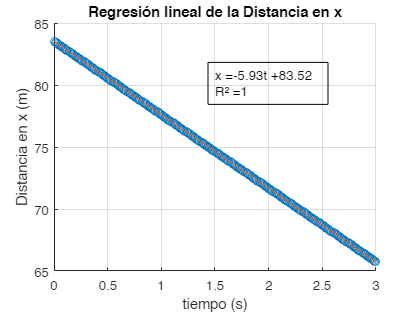

%importacion de datos
importdata("Data3.xlsx");

%Establicion de variables
x=table2array(Data3(:,"X"));
y=table2array(Data3(:,"Y"));
z=table2array(Data3(:,"Z"));
t=table2array(Data3(:,"time"));
T = [ones(length(t),1) t];

%Regresion lineal y graficación de x
figure(1)
bx = T\x;
xCalc = T*bx;
bx=round(bx,2);
Rsq2x = 1 - sum((x - xCalc).^2)/sum((x - mean(x)).^2);
scatter(t,x)
hold on
plot(t,xCalc)
xlabel('tiempo (s)')
ylabel('Distancia en x (m)')
dim = [.5 .5 .3 .3];
strx = {strcat('x = ',num2str(bx(2)),'t + ',num2str(bx(1))),strcat('R² = ',num2str(Rsq2x))};
annotation('textbox',dim,'String',strx,'FitBoxToText','on');
grid on
title('Regresión lineal de la Distancia en x')

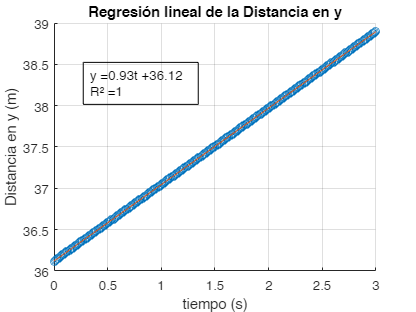



%Regresion lineal y graficación de y
figure(2)
by = T\y;
yCalc = T*by;
by=round(by,2);
Rsq2y = 1 - sum((y - yCalc).^2)/sum((y - mean(y)).^2);
scatter(t,y)
hold on
plot(t,yCalc)
xlabel('tiempo (s)')
ylabel('Distancia en y (m)')
dim = [.2 .5 .3 .3];
stry = {strcat('y = ',num2str(by(2)),'t + ',num2str(by(1))),strcat('R² = ',num2str(Rsq2y))};
annotation('textbox',dim,'String',stry,'FitBoxToText','on');
title('Regresión lineal de la Distancia en y')
grid on

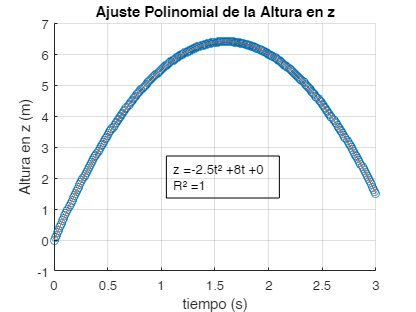


%Ajuste Polinomial y graficación de z
figure(3)
pz = polyfit(t,z,2);
zCalc = polyval(pz,t);
pz=round(pz,2);
Rsq2z = 1 - sum((z - zCalc).^2)/sum((z - mean(z)).^2);
scatter(t,z)
hold on
plot(t,zCalc)
xlabel('tiempo (s)')
ylabel('Altura en z (m)')
dim = [.4 .3 .2 .2];
strz = {strcat('z = ',num2str(pz(1)),'t² + ',num2str(pz(2)),'t + ',num2str(pz(3))),strcat('R² = ',num2str(Rsq2z))};
annotation('textbox',dim,'String',strz,'FitBoxToText','on');
title('Ajuste Polinomial de la Altura en z')
grid on


%Cálculo de Velocidad y gravedad
g=round(2*pz(1),2)

g = -5

v=round(sqrt(pz(2)^2+bx(2)^2+by(2)^2),2)

v = 10